AirQualityData=readtable("AirQualityData.csv");
Locations=readtable("Locations.csv");

latitude = Locations(:,2);
longitude = Locations(:,3);

latitude1 = table2array(latitude);
longitude1 = table2array(longitude);
geoscatter(latitude1(1),longitude1(1),'filled','bo');
hold on;

latitudeEPD = latitude1(11:13);
longitudeEPD = longitude1(11:13);
geoscatter(latitudeEPD,longitudeEPD,'filled','square')
hold on;

latitudeBad = latitude1(2:10);
longitudeBad = longitude1(2:10);
geoscatter(latitudeBad,longitudeBad,'filled','^');

legend('USEmbassy','EPD','Purple Air')
hold off;

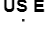

count=1;

for idx = 1:12
    for jdx = (idx+1):(13)
         Distances(jdx-1,idx) = haversine([latitude1(idx) longitude1(idx)],[latitude1(jdx) longitude1(jdx)]);
    end
end

US_embassy_distances = Distances(:,1);

X = categorical({'RenkeLUMS' 'PAirGardenTown' 'PAirDHAPhase2' 'PAirAnarkali' 'PAirHarbanspura' 'PAirDefenceChowk' 'PAirIqbalTown' 'PAirAkbarChowk' 'PAirTownship' 'MeTStation' 'Dental College' 'EPD Gulberg'});
X = reordercats(X,{'RenkeLUMS' 'PAirGardenTown' 'PAirDHAPhase2' 'PAirAnarkali' 'PAirHarbanspura' 'PAirDefenceChowk' 'PAirIqbalTown' 'PAirAkbarChowk' 'PAirTownship' 'MeTStation' 'Dental College' 'EPD Gulberg'});

bar(X,US_embassy_distances)

ylabel('Distances(KM)')
title('Distances from US Embassy Station')

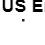


AQD1=table2array(AirQualityData((944:1114),2:14));

AQD2=[zeros];                                           % Initialization of arrays
AQD3=[zeros];

for idx1 = 1:12

          temp1=AQD1(:,1);                              % storing data in temporary variables
          temp2=AQD1(:,idx1+1);
          count2=0;                                     % counter initialization

    for jdx1=1:171
       
        if temp1(jdx1) ~= -1 && temp2(jdx1) ~=-1        % if conditional used to exclude data with missing entries

            count2=count2+1;
            AQD2(count2)=temp1(jdx1);
            AQD3(count2)=temp2(jdx1);

        end
    end

   AQD_Correlation=corrcoef(AQD2,AQD3);                 % using builtin function corrcoeff to compute correlation coefficient
   correlation_values(idx1)=AQD_Correlation(1,2);       % storing correlation coefficient in 'correlation_values'
   AQD2=AQD2.*0;                                        % emptying array to be used again 
   AQD3=AQD3.*0;

end

bar(X,correlation_values);
title('Correlation Coefficients of US Embassy with other stations')
ylabel('Correlation Coefficients')

AQD2=[zeros];                                            % Initialization of arrays
AQD3=[zeros];

Path1=[1 5 8 3 9 10 7 4 2];                              % Ideal pathways for computing calibration
Path2=[1 6];

AQD_calibrated1=[AQD1(:,1) AQD1(:,5) AQD1(:,8) AQD1(:,3) AQD1(:,9) AQD1(:,10) AQD1(:,7) AQD1(:,4) AQD1(:,2)];
AQD_calibrated2=[AQD1(:,1) AQD1(:,6)];                   % Extracting data to be calibrated for each pathway

for idx2 = 1:(length(Path1)-1)                           

          temp3=AQD1(:,Path1(idx2));                     % storing data in temporary variables
          temp4=AQD1(:,Path1(idx2+1));
          count2=0;                                      % counter initialization
         
    for jdx2=1:171
        
        if temp3(jdx2) ~= -1 && temp4(jdx2) ~=-1         % if conditional used to exclude data with missing entries
            count2=count2+1;
            AQD2(count2)=temp3(jdx2);
            AQD3(count2)=temp4(jdx2);
        end
    end

    calibration(idx2,1:2)=polyfit(AQD2,AQD3,1);          % Using polyfit and storing calibration values in 'calibration'
    AQD2=AQD2.*0;                                        % emptying array to be used again
    AQD3=AQD3.*0;

end



for n=2:9
    for m=1:171
        if AQD_calibrated1(m,n) ~= -1 && AQD_calibrated1(m,n-1) ~= -1                          % if conditional used to exclude data with missing entries
           AQD_calibrated1(m,n)=(AQD_calibrated1(m,n)-calibration(n-1,2))/calibration(n-1,1);  %Computing calibrated AQD values for each sensor
        end
    end
end


for idx2 = 1:(length(Path2)-1)                            % Repeating for second pathway 

          temp3=AQD1(:,Path2(idx2));
          temp4=AQD1(:,Path2(idx2+1));
          count2=0;
         
    for jdx2=1:171
        
        if temp3(jdx2) ~= -1 && temp4(jdx2) ~=-1
            count2=count2+1;
            AQD2(count2)=temp3(jdx2);
            AQD3(count2)=temp4(jdx2);
        end
    end

    calibration1(idx2,1:2)=polyfit(AQD2,AQD3,1);
    AQD2=AQD2.*0;
    AQD3=AQD3.*0;

end


n=2;

for m=1:171
        if AQD_calibrated2(m,n) ~= -1 && AQD_calibrated2(m,n-1) ~= -1
           AQD_calibrated2(m,n)=(AQD_calibrated2(m,n)-calibration1(n-1,2))/calibration1(n-1,1);
        end
end

Calibrated_AQD_Final = [AQD_calibrated1(:,1) AQD_calibrated1(:,9) AQD_calibrated1(:,4) AQD_calibrated1(:,8) AQD_calibrated1(:,2) AQD_calibrated2(:,2) AQD_calibrated1(:,7) AQD_calibrated1(:,3) AQD_calibrated1(:,5) AQD_calibrated1(:,6)]

Calibrated_AQD_Final =    92.8750   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   37.1250   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   84.5833   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   43.9167   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   36.6168   -1.0000   -1.0000
   52.7917   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   48.7324   -1.0000   -1.0000
   -1.0000   -1.0000   49.7948   -1.0000   -1.0000   -1.0000   -1.0000   49.0154   -1.0000   -1.0000
   -1.0000   -1.0000   90.8948   68.5518   -1.0000   -1.0000   -1.0000   89.7204  108.5160   81.4199
   -1.0000   -1.0000   77.8632   65.3715   82.4765   65.8328   -1.0000   81.0593   86.0602   74.4312
   -1.0000   -1.0000   56.3829   54.3017   72.5839   64.6782   -1.0000   65.3362   56.4558   57.5209
   -1.0000   -1.0000   52.8624   52.4056   80.5738   65.7421   -1.00


% Storing all columns of calibrated AQD data in order in 'Calibrated_AQD_Final'


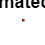

LUMS_distances=[Distances(1,1)                         %cExtracting distances of other sensors(Computed in task 2) from LUMS sensor and storing in 'LUMS_distances'
    Distances(2:12,2)];

AQD5=Calibrated_AQD_Final(1:145,:);                    % Extracting calibrated data(computed in task 4) of the required dates and storing them in 'AQD5'

temp5=AQD5(:,2);                                       % Switching columns of RENKE_LUMS data and US_Embassy data for ease of calculation
AQD5(:,2)=AQD5(:,1);
AQD5(:,1)=temp5;
temp6=0;                                               % Variable initialization

for IDX=1:145 
     W=0;                                              % Variable initialization
    for JDX=1:10
      
        if AQD5(IDX,JDX)~=-1                           % if conditional used to exclude data with missing entries
            w=1/(LUMS_distances(JDX));                 % Calculating inverse distances 
            W=W+w;                                     % Calculating sum of inverse distances 
            temp6=temp6+(w)*AQD5(IDX,JDX);             % Calculating total sum for final estimated AQD data
        end
    end
 
  LUMS_EstimatedData(IDX)=temp6/W;                     % Storing estimated data in 'LUMS_EstimatedData'
  temp6=0;

end

Date=AirQualityData((944:1088),1);
Dates=table2array(Date);
plot(Dates,LUMS_EstimatedData,'r');
xlabel('Dates')
ylabel('Estimated PM2.5 Concentrations')
title('RENKE_LUMS Estimated Data Over Time')